#  Example

## Introduction 

This example illustrates the calculation of the Obukhov length using the eddy covariance method. The inputs are time series of the along and vertical wind velocity components and the potential temperature at three different positions on a "virtual" met mast. A comparison between the target and simulated spectra is provided, where the target spectra are taken from Højstrup [1], which is used to generate the surface wind spectra for unstable and neutral stratification. No model is provided for the stable stratification, so this case is not investigated in the following.

###  Notations

-   $$\theta$$: potential temperature (K)

-   $u$: along-wind wind component (m/s)

-   $v$: across-wind wind component (m/s)

-   $w$:  vertical wind component (m/s)

-   $u_*$: friction velocity (m/s)

-   $T_*$: scaling temperature (K)

-   $\phi_M$: similarity function for the momentum flux (wind shear) - no dimensions

-   $z_i$: Lowest inversion height (m)

-   $t$: time vector (s)

###  Assumptions

-    The humidity flux is not modelled here, so that the humidity is assumed negligeable. In other words, virtual potential temperature = potential temperature.

-   The turbulent flow is a stationary, homogeneous ergodic random process.

-   The Monin-Obukhov Similarity Theory (MOST) is assumed to be verified.

###  Definitions

 Obukhov length [2]: $L = -\frac{\overline{\theta_v} u^3_{*_0}}{g \kappa (\overline{w^{\prime}\theta_v^{\prime}})_0}$

One-dimensional stability parameter (zL): $ $\zeta = \frac{z}{L}$$

 Friction velocity (u_star): $ $u_{*} = \left( \overline{u^{\prime}w^{\prime}}^{2}+\overline{u^{\prime}v^{\prime}}^{2}\right)^{1/4}$$

 Scaling temperature (T_star): $ $T_{*} = -\frac{\overline{w^{\prime}\theta_{v}^{\prime}}}{u_*}$$

 Non-dimensional velocity profile: $ $\phi_m = \frac{\kappa z}{u_*}\frac{\partial\overline{u}}{\partial z}.$$

 Empirical formulation of $$\phi_m$$ [3,4]: $\left\lbrace
\begin{array}{ll}
 \phi_m = \left(1+15.2 |\zeta|\right)^{-1/4} & \text{if } -2 \leq \zeta \leq 0 \\
\phi_m =  1 + 4.8\zeta & \text{if }  0 \leq \zeta \leq 1 
\end{array}\right.$

### References

  [1] Højstrup, J. (1981). A simple model for the adjustment of velocity spectra in unstable conditions downstream of an abrupt change in roughness and heat flux. Boundary-Layer Meteorology, 21(3), 341-356.

 [2] Monin, A. S., & Obukhov, A. M. F. (1954).  Basic laws of turbulent mixing in the surface layer of the atmosphere.  Contrib. Geophys. Inst. Acad. Sci. USSR, 151(163), e187. 

 [3] Högström, U. L. F. (1988). Non-dimensional wind and temperature  profiles in the atmospheric surface layer: A re-evaluation.  Boundary-Layer Meteorology, 42(1), 55-78. 

 [4] Dyer, A. J. (1974). A review of flux-profile relationships.  Boundary-Layer Meteorology, 7(3), 363-372.

## Preliminary steps and data loading

Load simulated data:  Each sample contains 6 variables: t,u,w,nodes,theta and zi. The  variable "nodes" is a structure containing information about the simulated mast. The across-wind component is neglected

clearvars;close all;clc;
kappa = 0.4; % von karman constant
COLOR = {'k','r','b'}; 
data = dir('Sample_L_*');

clear z meanU L wT *_star U
for ii=1:numel(data)
    load(data(ii).name);
    z(ii,:) = nodes.Z;
    U(ii,:) = mean(u,'omitnan');
    Theta(ii,:) = mean(theta,'omitnan');
    fprintf(['Summary of data set ',num2str(ii),': \n']);
    [L(ii,:),wT(ii,:),T_star(ii,:),u_star(ii,:)] = getStability(u,w,theta,nodes.Z); % the 'v' parameter (crosswind component) is optional
end

Summary of data set 1: 


Estimated T* = -0.016 K 
Estimated u* = 0.62 m/s 
Estimated heat flux wT = 0.01 
Estimated L = -1663 m 



Summary of data set 2: 


Estimated T* = -1.7 K 
Estimated u* = 0.63 m/s 
Estimated heat flux wT = 1.1 
Estimated L = -16 m 



Summary of data set 3: 


Estimated T* = -0.78 K 
Estimated u* = 0.63 m/s 
Estimated heat flux wT = 0.49 
Estimated L = -36 m 



Summary of data set 4: 


Estimated T* = -3.1 K 
Estimated u* = 0.6 m/s 
Estimated heat flux wT = 1.8 
Estimated L = -8 m 




fs = 1/median(diff(t)); % sampling frequency
z = mean(z);% z is the same for every samples
zL = bsxfun(@times,z,1./L);
% According to the MOST, wT and u_star are constant in the sruface layer:
u_star = mean(u_star,2,'omitnan');
T_star = mean(T_star,2,'omitnan');
wT = mean(wT,2,'omitnan');

## Non-dimensional profile of mean wind speed 

Comparison with similarity functions for momentum. The reference similarity functions are taken from Högström [3], based on the works of Dyer et al. [4]

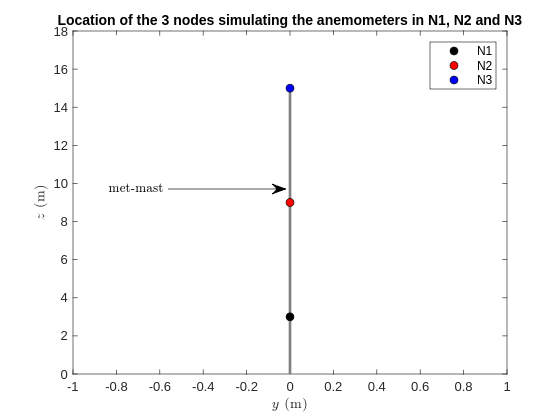

figure
hold on, box on;
plot([0,0],[0,15],'color',[0.5,0.5,0.5],'linewidth',2);
for ii=1:numel(z)
    h(ii) = plot(nodes.Y(ii),nodes.Z(ii),'ko','markerfacecolor',COLOR{ii});
end
legend(h,nodes.name{:})
hold on
ylim([0,18])
ylabel('$z$ (m)','interpreter','latex')
xlabel('$y$ (m)','interpreter','latex')
set(gcf,'color','w')
title('Location of the 3 nodes simulating the anemometers in N1, N2 and N3')
annotation('textarrow',[0.3,0.51],[0.55,0.55],'String','met-mast ','interpreter','latex')

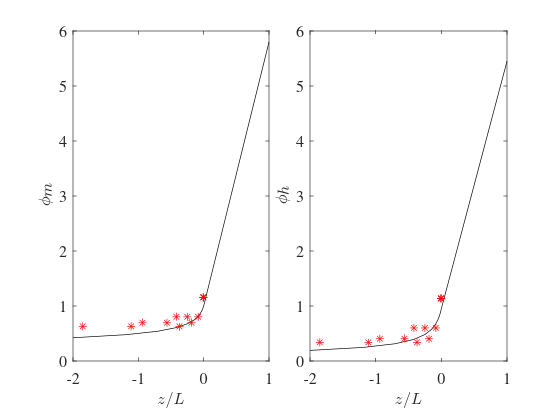


figure
plotSimilarityFun(z,zL,u_star,T_star,U,Theta);

## Overview of the target Su and Sw spectra

Overview of the target spectra for the along-wind velocity component. Each panel corresponds to a different stability, characeterized by a given value of the Obukhov length.

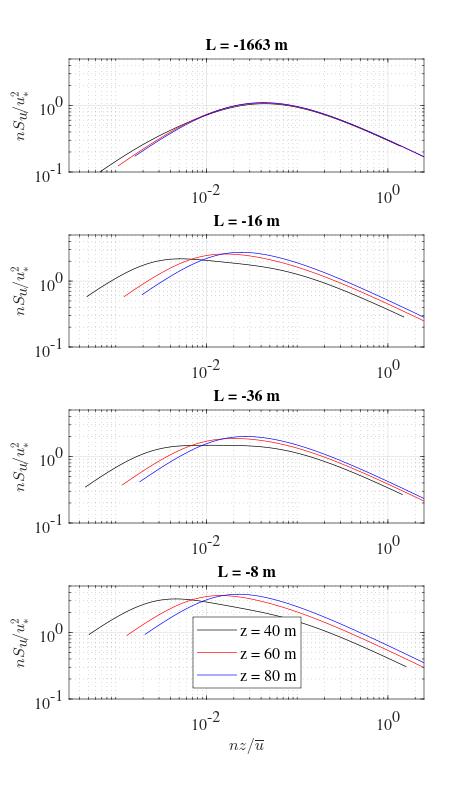

Normalization = 1; % We want the normalized spectra (otherwise Normalization =  0)
f = logspace(-3,0.5,100);
Su = zeros(numel(data),numel(z),numel(f));
Sw = zeros(numel(data),numel(z),numel(f));
for ii=1:numel(data)
    for jj=1:numel(z)
        fr = f*z(jj)/U(ii,jj);
        fi = f*zi/U(ii,jj); % zi is the inversion height
        Su(ii,jj,:) = longitudinalSpectrum_Hojstrup(u_star(ii),L(ii),f,fr,fi,zi,Normalization);
        Sw(ii,jj,:) = verticalSpectrum_Hojstrup(u_star(ii),z(jj),L(ii),f,fr,Normalization);
    end
end

clf;close all
figure('position',[500         193         469         785]);
tiledlayout(4,1,"TileSpacing","tight")
for ii=1:numel(data)
    nexttile
    for jj=1:numel(z)
        hold on;box on;
        plot(f*z(jj)/U(ii,jj),squeeze(Su(ii,jj,:)),COLOR{jj});
        ylabel('$n S_u / u^2_*$','interpreter','latex')
        grid on
        ylim([0.1,5]);
        xlim([1/t(end),fs/2]);
        title(['L = ',num2str(round(L(ii))),' m'],'FontSize',8)
    end
    set(gca,'Xscale','log','Yscale','log');
    if ii==4
        xlabel('$nz/\overline{u}$','interpreter','latex')
        legend('z = 40 m','z = 60 m','z = 80 m','location','south')
    end
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

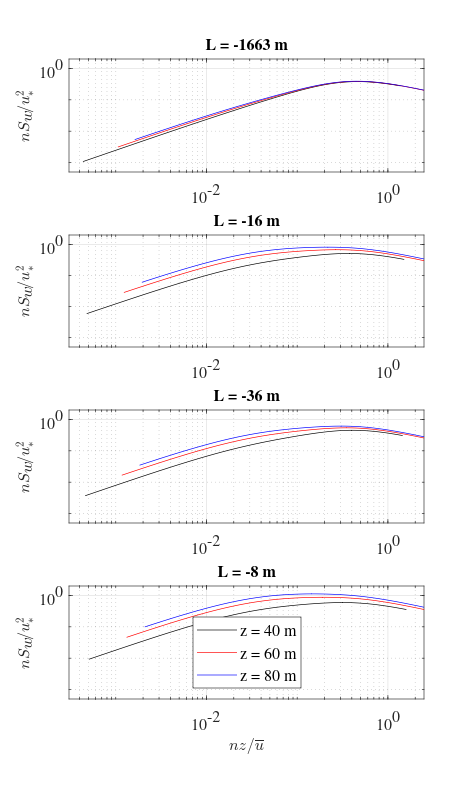

set(gcf,'color','w')

COLOR = {'k','r','b'};
clf;close all
figure('position',[500         193         469         785]);
tiledlayout(4,1,"TileSpacing","tight")
for ii=1:numel(data)
    nexttile
    for jj=1:numel(z)
        hold on;box on;
        plot(f*z(jj)/U(ii,jj),squeeze(Sw(ii,jj,:)),COLOR{jj});
        
        ylabel('$nS_w/u^2_*$','interpreter','latex')
        grid on
        ylim([0.0005,2]);
        xlim([1/t(end),fs/2]);
        title(['L = ',num2str(round(L(ii))),' m'],'FontSize',8)
    end
    set(gca,'Xscale','log','Yscale','log');
    if ii==4,
        legend('z = 40 m','z = 60 m','z = 80 m','location','south');  
        xlabel('$nz/\overline{u}$','interpreter','latex')
    end
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

set(gcf,'color','w')

## Overview of the computed spectra

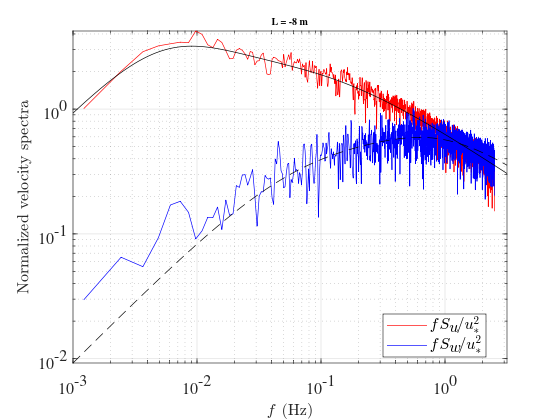

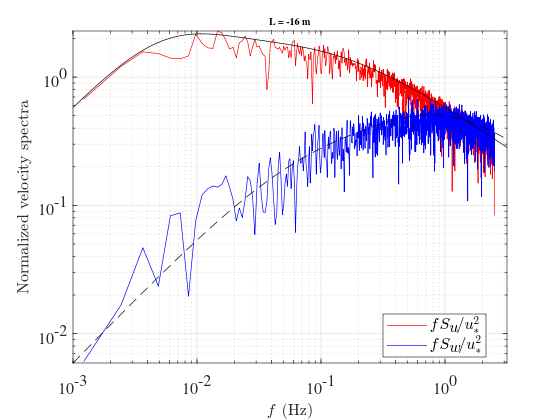

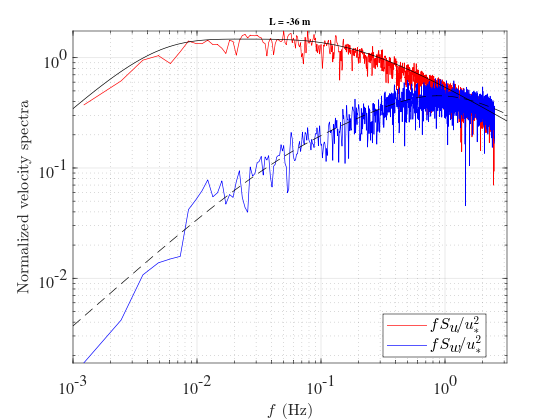

clf;close all;
for ii=1:numel(data)
    load(data(ii).name,'u','w','t');
    fs = 1./median(diff(t));
    figure    
    plotVelocitySpectra(u,w,fs,squeeze(Su(ii,1,:))',squeeze(Sw(ii,1,:))',f,u_star(ii))
    title(['L = ',num2str(round(L(ii))),' m'],'FontSize',8)
end